DNN

% housekeeping 

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions');
addpath(function_folder)

d = struct;
cfg = struct;

% get subject numbers
cfg.exp_num = 2;
if cfg.exp_num == 1
    cfg.subNums = 4:37;
elseif cfg.exp_num == 2
    cfg.subNums = [102:108, 110:136];
end
cfg.n = length(cfg.subNums);

% other standard configurations
cfg.categories = {'bathroom', 'kitchen'};
cfg.colormaps = load('white_zero_colormap.mat');
cfg.FontName = 'Helvetica';
cfg.FontSize = 15;


% load images and get DNN representation
images = load_images(cfg);

% typical images 
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

% control images 
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);


Gaze

%a_preprocessing(cfg)
%b_detFix(cfg)
%c_showFix
%d_AOIfix(cfg)

e_getGazePatterns(cfg);
e_getGazePatterns_firstFix(cfg);

cfg.variables_of_interest = {'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectDwellsCateEven', 'ObjectDwellsCateOdd',...
    'ObjectsCate_firstFix', 'ObjectsCate_firstFixEven', 'ObjectsCate_firstFixOdd',...
    'IndividualObjectDwells', 'IndividualObjects_firstFix',...
    'ObjectCatePrio', 'ObjectCatePrioOdd', 'ObjectCatePrioEven'};
 d = makeGDM(d, cfg);
 d = regressOutMean(d, cfg);


Split half correlation

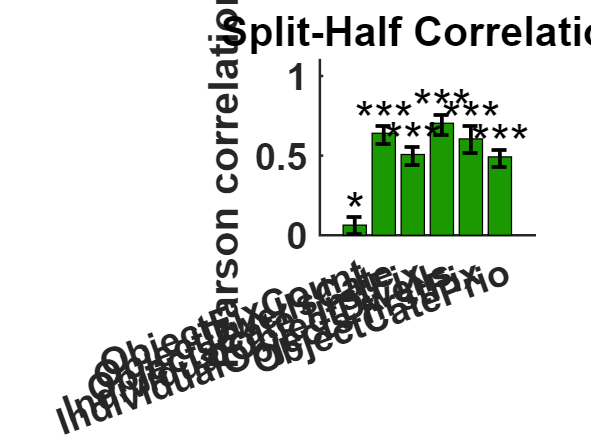

% split half correlation
cfg.regressOutMean = true;
cfg.variables_of_interest = {'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectsCate_firstFix',...
    'IndividualObjectDwells', 'IndividualObjects_firstFix',...
    'ObjectCatePrio'};
cfg.correlation_type = 'pearson';
d = getSpliHalfReliability(d, cfg);
plotSpliHalfReliability(d, cfg);

Get inter-subject correlation

Plotting and saving inter-subject RDM for task:ObjectFixCount and bathroom


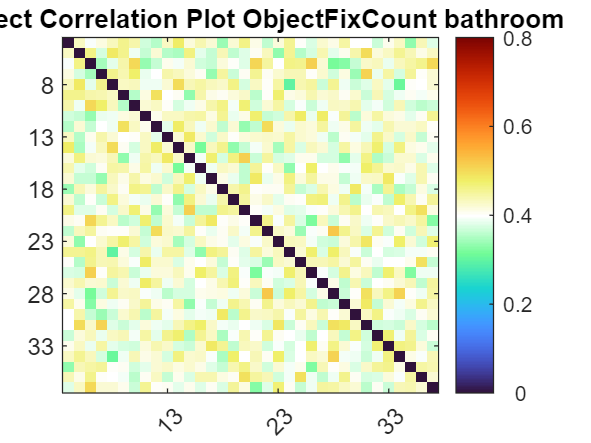

Plotting and saving inter-subject RDM for task:ObjectDwellsCate and bathroom


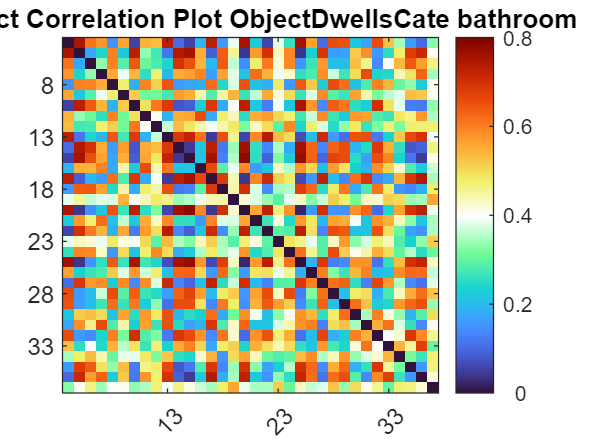

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and bathroom


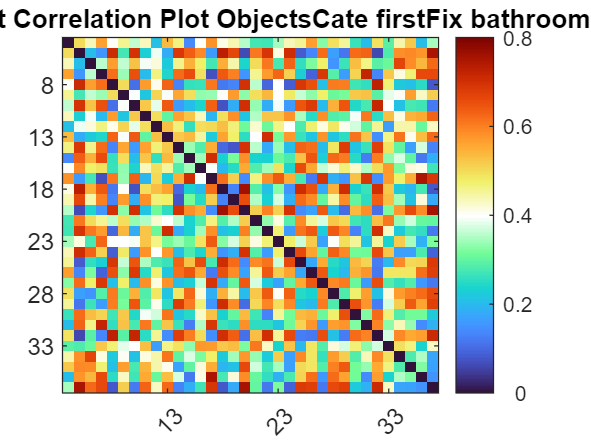

Plotting and saving inter-subject RDM for task:IndividualObjectDwells and bathroom


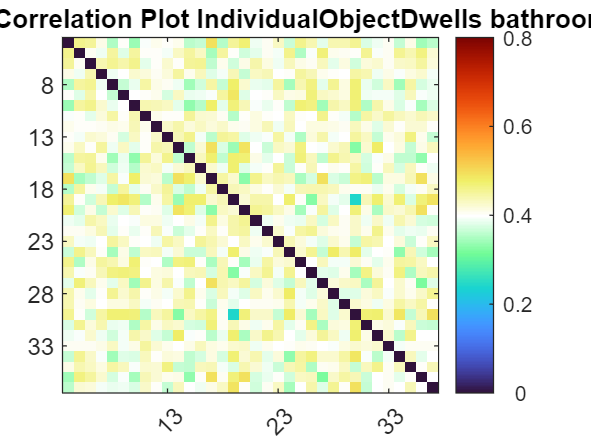

Plotting and saving inter-subject RDM for task:IndividualObjects_firstFix and bathroom


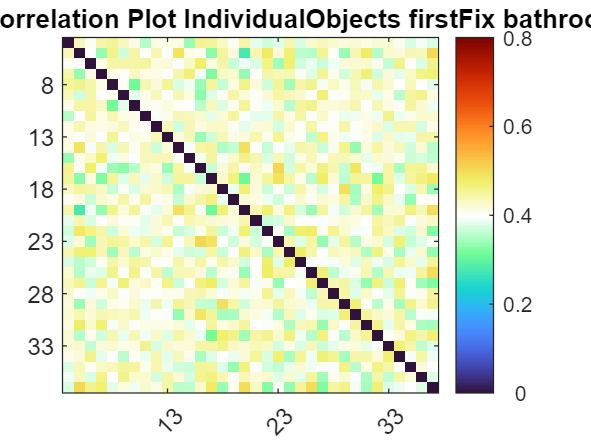

Plotting and saving inter-subject RDM for task:ObjectCatePrio and bathroom


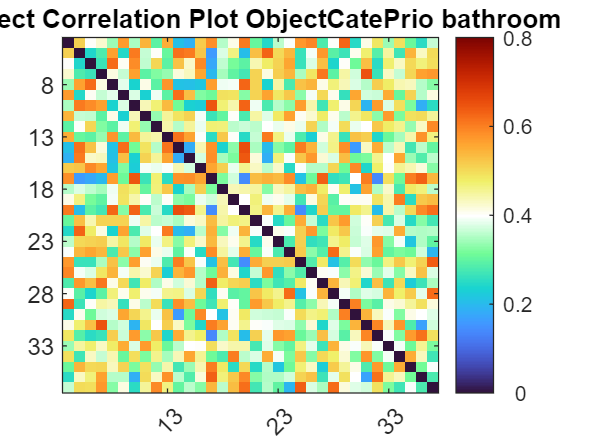

Plotting and saving inter-subject RDM for task:ObjectFixCount and kitchen


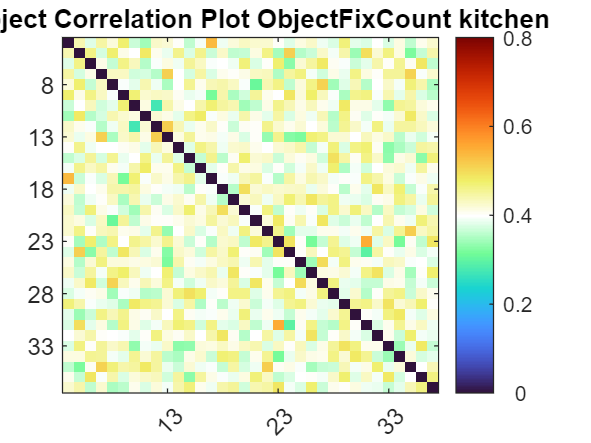

Plotting and saving inter-subject RDM for task:ObjectDwellsCate and kitchen


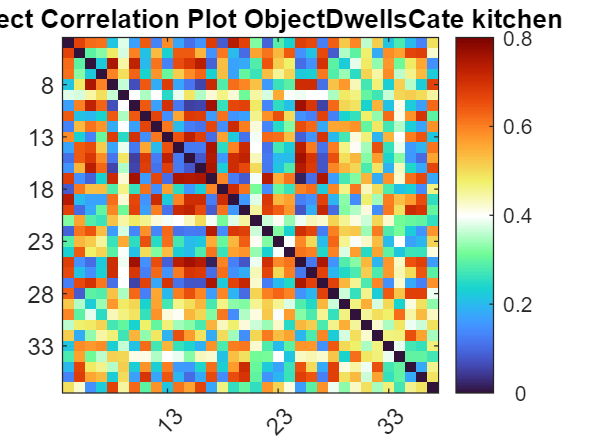

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and kitchen


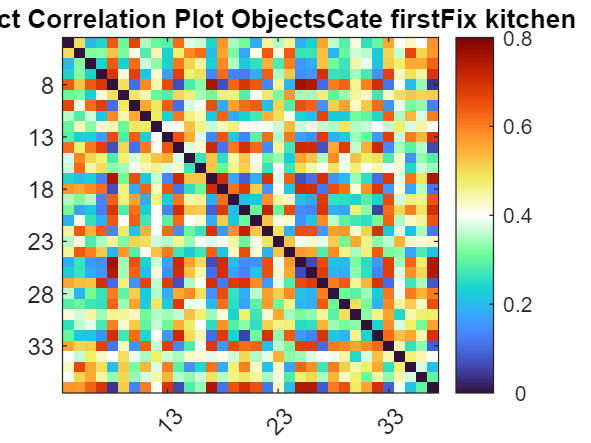

Plotting and saving inter-subject RDM for task:IndividualObjectDwells and kitchen


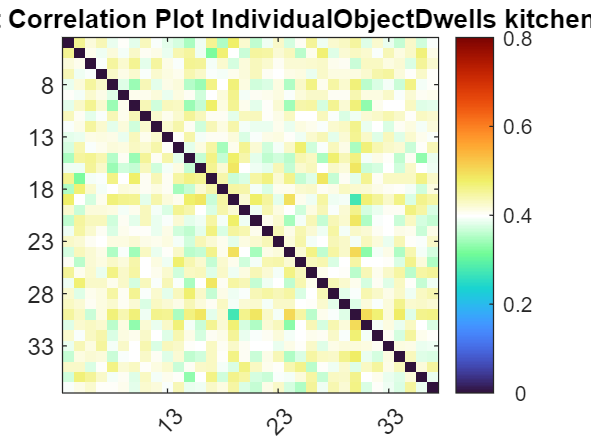

Plotting and saving inter-subject RDM for task:IndividualObjects_firstFix and kitchen


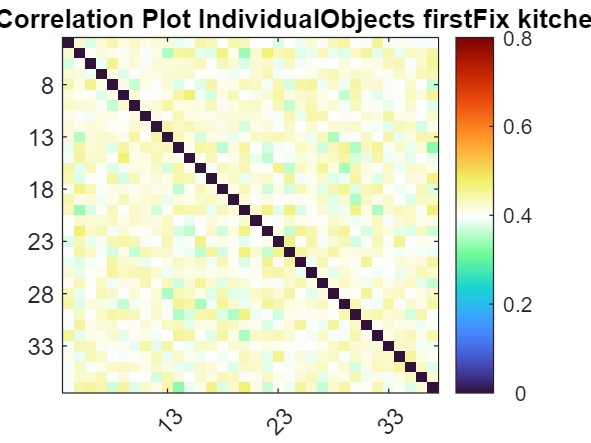

Plotting and saving inter-subject RDM for task:ObjectCatePrio and kitchen


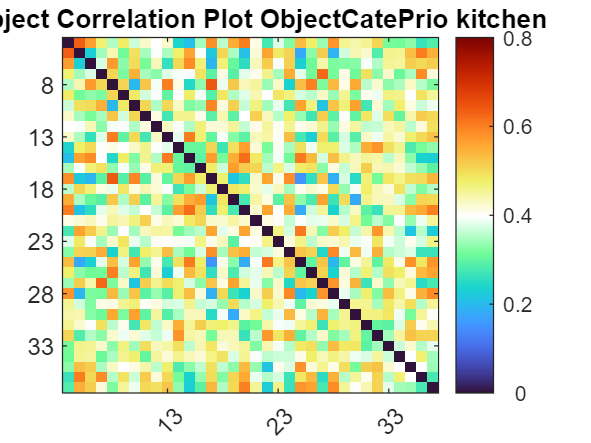

Compare categories


cfg.regressOutMean = true;
d = intersub_cor(d, cfg);

Get gaze distance

d = getGazeDist(d, cfg);


Compare them

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of GazeDist bathroom is done
20% of permutations of GazeDist bathroom is done
30% of permutations of GazeDist bathroom is done
40% of permutations of GazeDist bathroom is done
50% of permutations of GazeDist bathroom is done
60% of permutations of GazeDist bathroom is done
70% of permutations of GazeDist bathroom is done
80% of permutations of GazeDist bathroom is done
90% of permutations of GazeDist bathroom is done
100% of permutations of GazeDist bathroom is done
Compare inter-subject RDM of GazeDist with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of GazeDist kitchen is done
20% of permutations of GazeDist kitchen is done
30% of permutations of GazeDist kitchen is done
40% of permutations of GazeDist kitchen is done
50% of permutations of GazeDist kitchen is done
60% of permutations of GazeDist kitchen is done
70% of permut

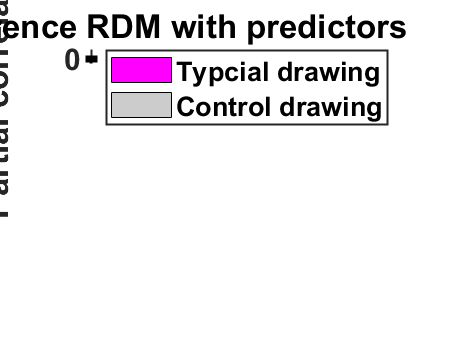

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectsCate_firstFix',...
    'IndividualObjectDwells', 'IndividualObjects_firstFix',...
    'ObjectCatePrio'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ylim = [-.25, .45];
cfg.partial_correlation_type = 'pearson';

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

Compare drawing oder and fixation order

cfg.partialCorr = true; % control for object size in stimuli
d = evaluateDrawingOrder(d, cfg)


Compare gazeDist in bined time windows

 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated


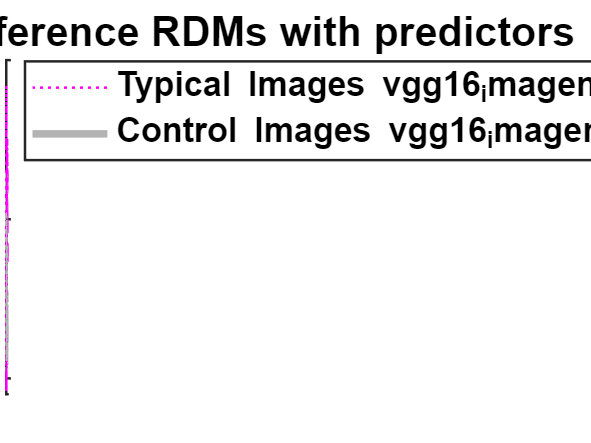

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'GazeDist'};
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = false;
cfg.ylim = [-.21, .41];
cfg.partial_correlation_type = 'pearson';

d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

Get memory task performance

if cfg.exp_num == 2
    d = getAccuracyMemoryTask(cfg, d)
end
